# Reconstruction and Signal Holders

In computer control systems, different signal types exist such that the continous-time system works in conjunction with a digital controller that operates in discrete-time. This file summarises some of the core concepts concisely and outlines the files available to investigate this. A particular focus is on the reconstruction of continouous time signals from a discrete signal.

$\bullet$ Perform numerical experiments on ideal reconstruction of sampled signals with examples and exercises.

$\bullet$ See time domain and frequency domain mathematical representations of implementable approximate reconstruction of sampled signasl with zero-order and first order holds.

$\bullet$ Perform numerical experiments and visiualizations of approximate reconstruction of sampled signals with zero-order hold and first order hold via examples and exercises, and further investigate the related concepts via directed Apps.

Several virtual laboratory files can be used in parallel to investigate the core concepts: 

- ***Signal_Types_in_Computer_Controlled_Systems_control101.mlapp***

- ***Analog_to_Digital_Converter_Application_control101.mlapp.***

- ***Digital_to_Analog_Converter_Application_control101.mlapp.***

This livescript introduces some of the core concepts alongside examples of MATLAB coding to  illustrate the core concepts. 

For further background on the analysis of sampling see the files: ***Sampling_Operation_control101.mlx, Continuous_and_Discrete_time_Mapping_control101.mlapp,  Closed_Loop_Under_Sampling_control101.mlapp, Sampled_Data_Systems_control101.mlx, Signal_Types_in_Computer_Controlled_Systems_control101, Signal_Types_in_Computer_Controlled_Systems_control101.mlx. ***

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%  
%        help control101         (opens within the command window)

Source files created by Mehmet Kilic, Yaprak Yalcin, Istanbul Technical University (İTÜ) and also available separately from [https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9](https://drive.mathworks.com/sharing/bf093c57-7f71-4380-bec3-c0fa6ffdb8b9)

Files edited for inclusion in the toolbox by J.A.Rossiter, University of Sheffield    

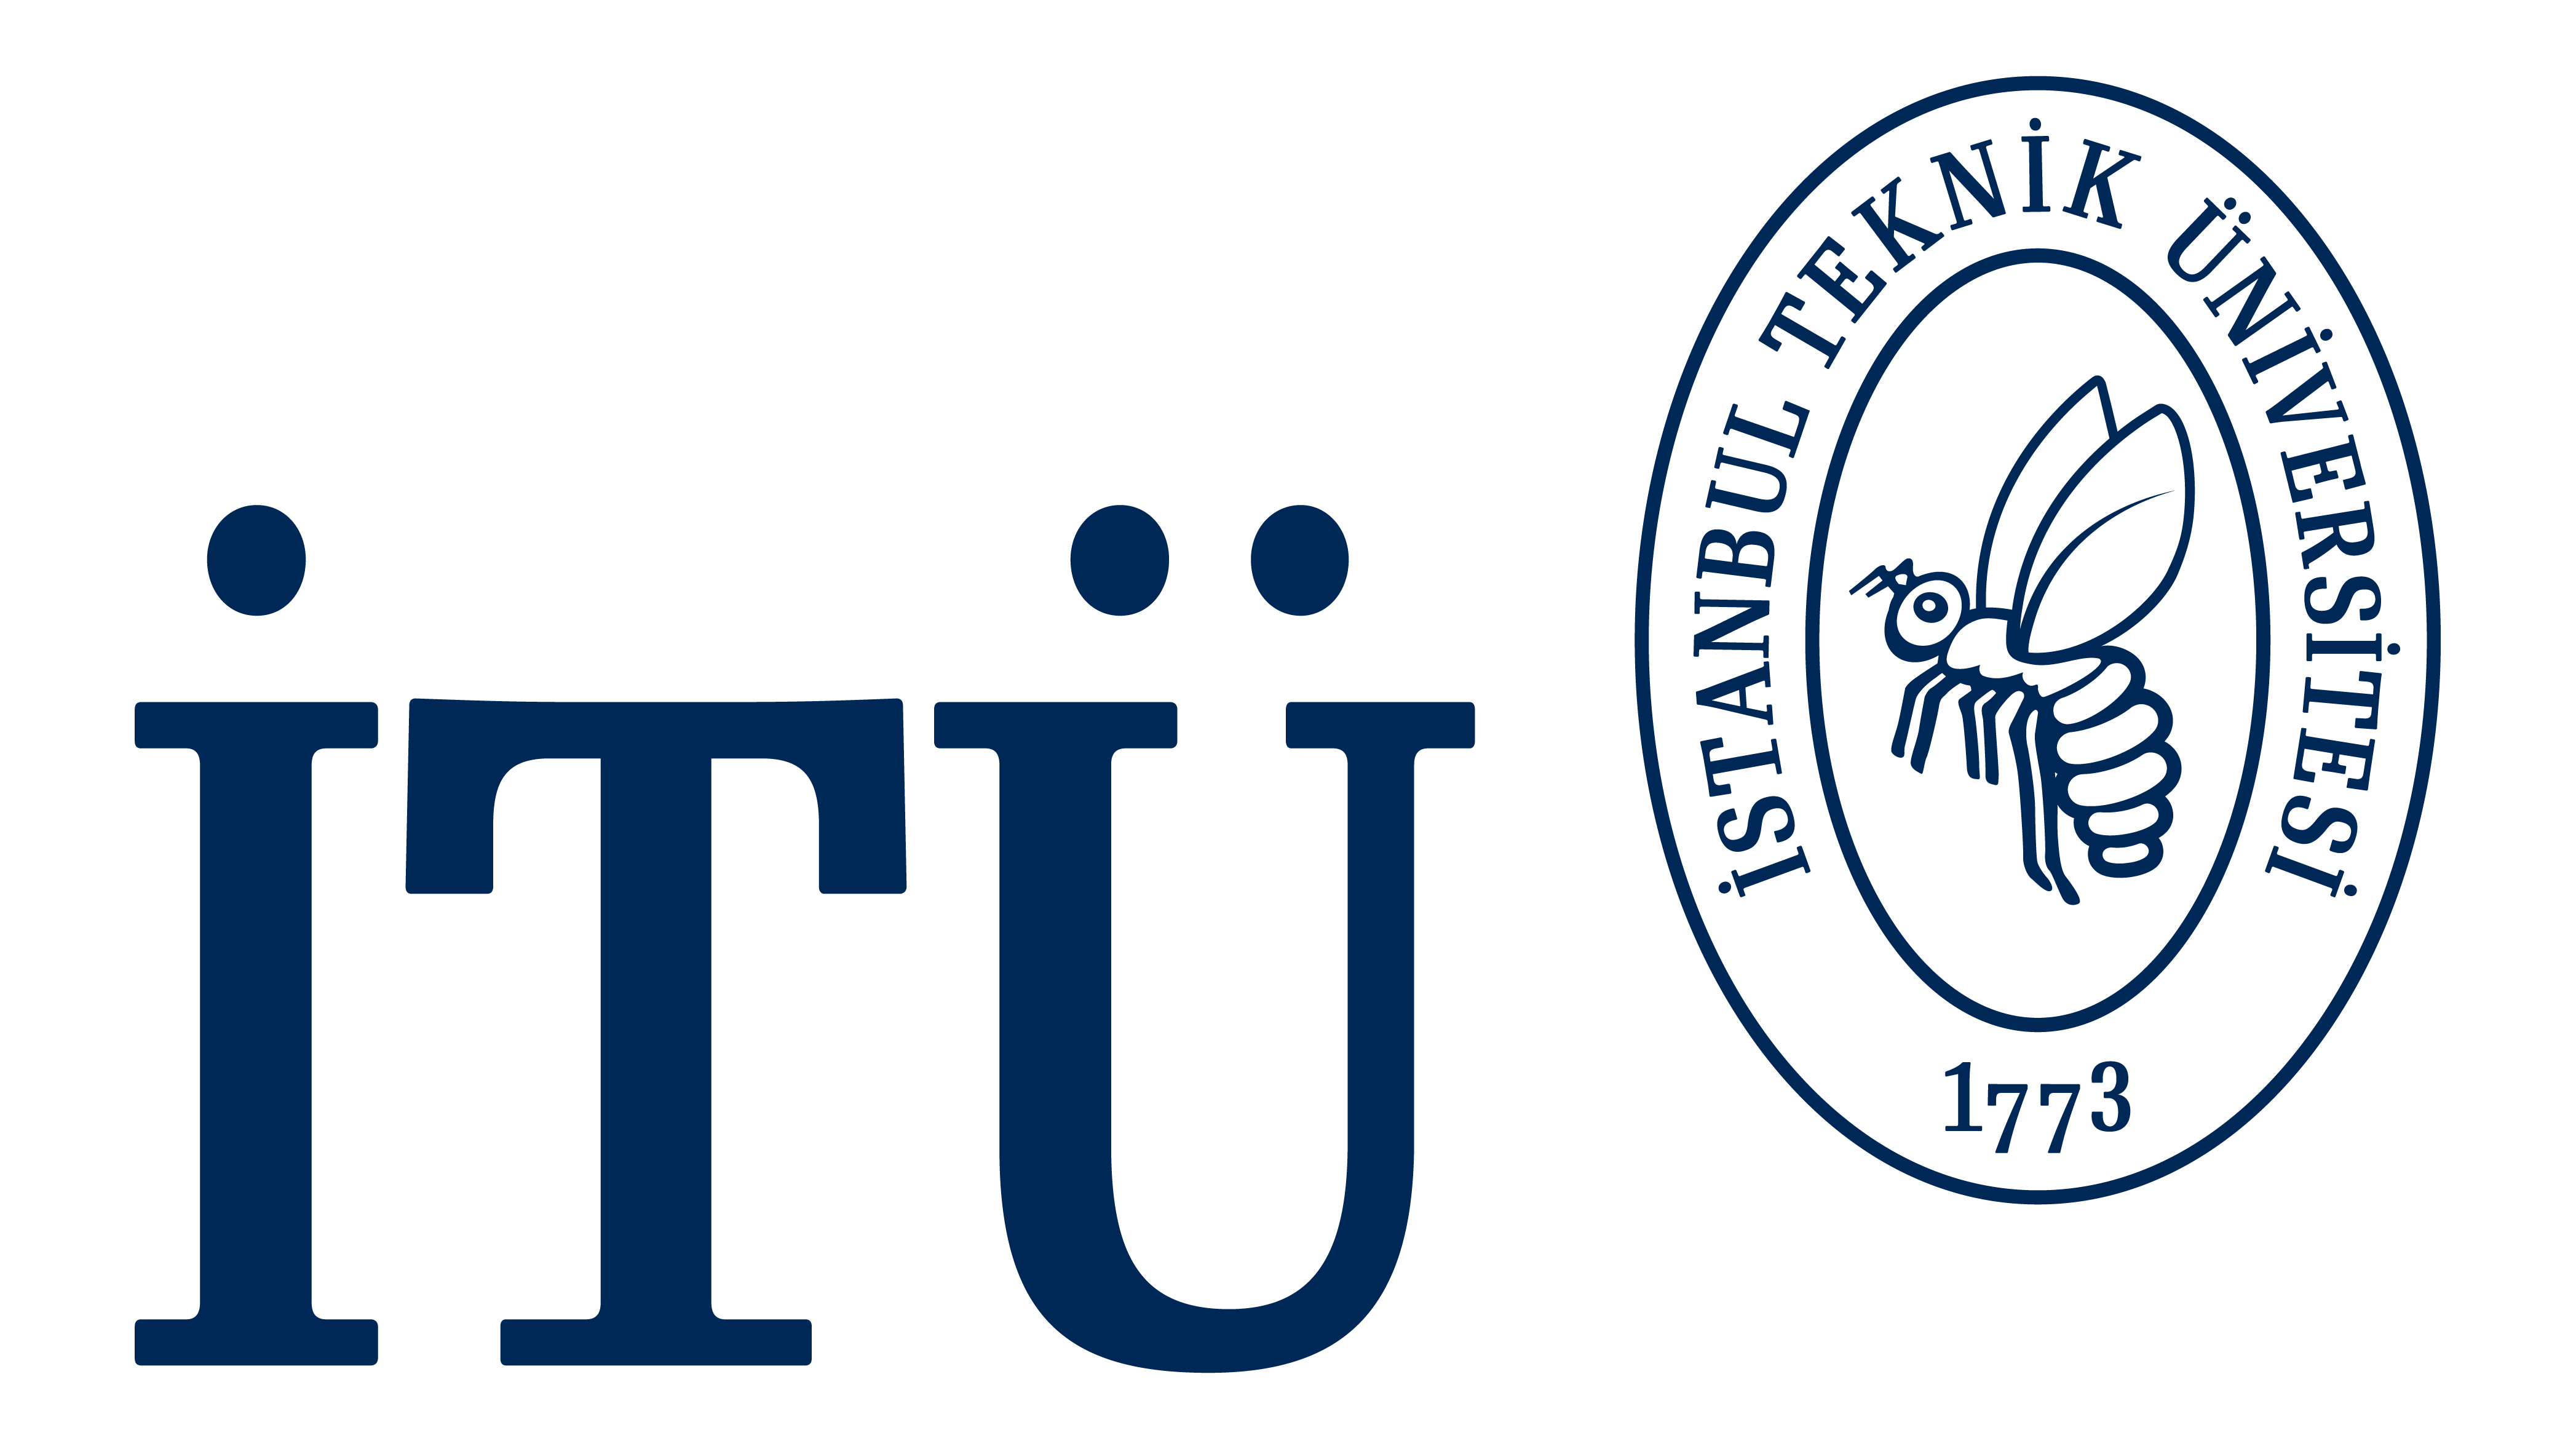

## Table of contents

- Introduction to sampled signals and the ideal filter

- Alternatives to an ideal filter

- Virtual laboratories

## 1 Introduction to sampled signals and the ideal filter

Theoretically it is possible to reconstruct  a band-limited orginal signal with an ideal filter for $\omega_s \ge 2\omega_c$ ($\omega_s$ the sampling frequency and $\omega_c$ the highest frequency in the band-limited signal) as seen Figure 1 and Figure 2 ($x_p$is the sampled signal and $x_r$ the reconstructed signal). Figure 2 shows band-limited filter spectrum together with spectrum of the sampled signal. As it is easy to see from the figure, with an ideal filter $H\left(\textrm{jw}\right)$, multiplications of spectrums in the frequency domain yields the spectrum of the orginal signal. 

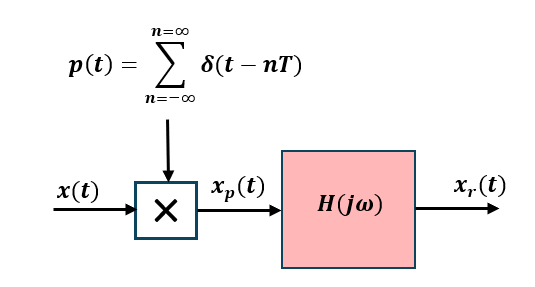

Figure 1: Sampling and reconstruction

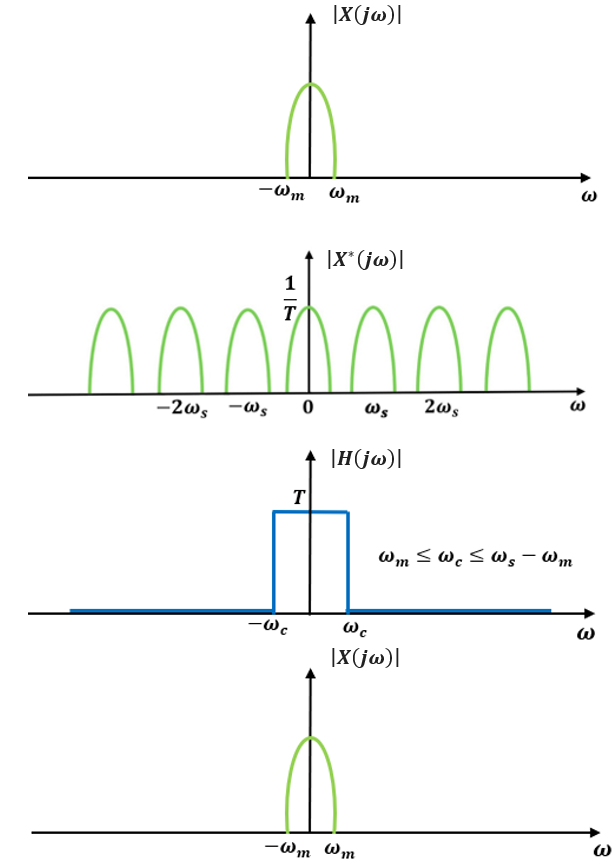

Figure 2 Reconstruction with an Ideal filter

### 1.1 Mathematical analysis of sampling and reconstruction

The Fourier transform (frequency spectrum) $P\left(j\omega \right)$ of the impulse train $p\left(t\right)$ is as follows.

### 
$$P\left(j\omega \right)=\frac{2\pi }{T}\sum_{n=-\infty }^{+\infty } \delta \left(j\left(\omega -\mathit{\mathbf{n}}\omega_{s\;} \right)\right);\;\;\;\;p\left(t\right)=\sum_{n=-\infty }^{+\infty } \delta \left(t-\textrm{nT}\right)$$


Therefore the frequency spectrum of the sampling signal with convolution in the frequency domain is obtained as below. This is a periodic spectrum as seen in Figure 2.

### 
$$\begin{array}{l}
X_{p\;} \left(j\omega \right)=\int_{-\infty }^{+\infty } X\left(j\theta \right)P\left(j\left(\omega -\theta \right)\right)d\theta \\
X_{p\;} \left(j\omega \right)=\frac{1}{T}\sum_{n=-\infty }^{+\infty } X\left(j\left(\omega -\mathit{\mathbf{n}}\omega_{s\;} \right)\right)
\end{array}$$


Multiplication of frequency spectrum of ideal filter (given by the blue line in Figure 2) with the frequency spectrum of sampled signal in frequency domain yields the frequency spectrum of the original (reconstructed) continous-time signal as seen in the figure. 

### 
$$X_{r\;} \left(j\omega \right)=H\left(j\omega \right)X_p \left(j\omega \right)$$


The impulse response of ideal filter is given in Figure 3. Convolution of this with the sampled signal gives following time domain function for the reconstructed signal. 

### 
$${\mathit{\mathbf{x}}}_{\mathit{\mathbf{r}}} {\left(\mathit{\mathbf{t}}\right)}=\sum_{\mathit{\mathbf{n}}=-\infty }^{\mathit{\mathbf{n}}=\infty } \mathit{\mathbf{x}}\left(\mathit{\mathbf{n}}\mathit{\mathbf{T}}\right)\frac{\omega_{\mathit{\mathbf{c}}} \mathit{\mathbf{T}}}{\pi }\frac{\mathit{\mathbf{s}}\mathit{\mathbf{i}}\mathit{\mathbf{n}}\left(\omega_{\mathit{\mathbf{c}}} {\left(\mathit{\mathbf{t}}-\mathit{\mathbf{n}}\mathit{\mathbf{T}}\right)}\right)}{\omega_{\mathit{\mathbf{c}}} {\left(\mathit{\mathbf{t}}-\mathit{\mathbf{n}}\mathit{\mathbf{T}}\right)}}$$


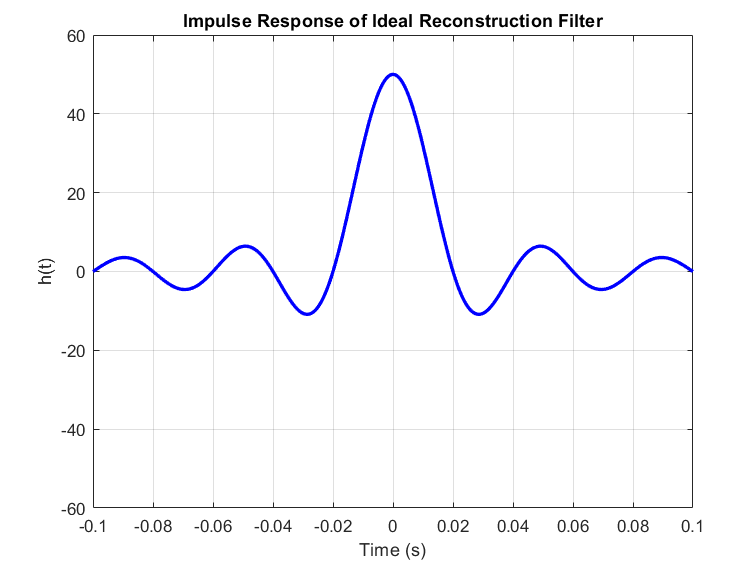

Figure 3 Impulse response of ideal filter

The frequency ${w_s =2\omega }_{m\;}$is important for the possibility of reconstruction and this is called the Nyquist (Shannon) frequency. The filter for the Shannon reconstruction is not causal, as evident from Figure 3. This means it is impossible to implement an ideal filter in practice as it is not physically realisable. Consequently, simpler and less accurate reconstructions, such as the zero-order hold and first-order hold are used. In Figure 4, the reconstruction of a continous signal with convolution of the sinc function with a sampled signal (weighted and shifted sum of sinc functions) is shown.

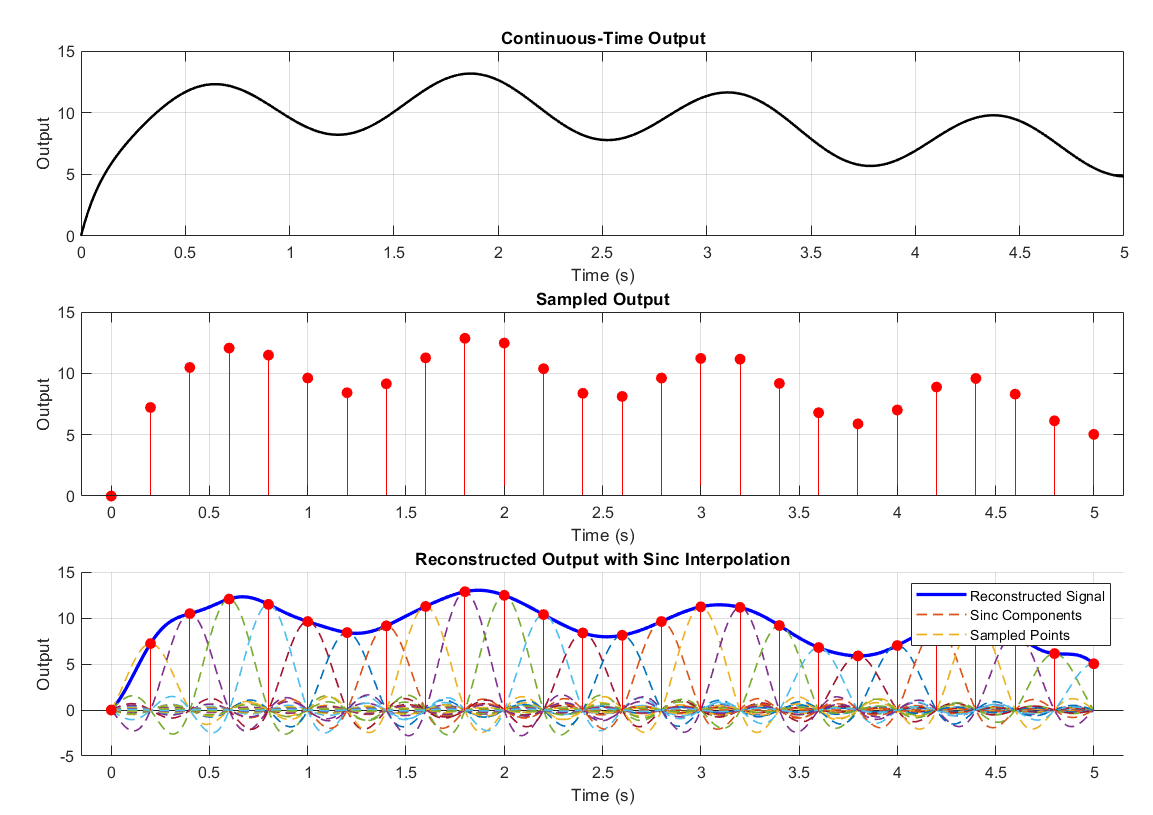

Figure 4. Time domain demonstration of reconstruction of a continous time signal with an ideal filter

### 1.2 Illustration of sampling and reconstruction 

Consider a linearized and reduced model of the Fan and Plate system. The following code plots the continuous output, the sampled output for Ts=0.5  and reconstructed continuous output with an ideal filter for the input signal u(t)=10 + 2sin(t)+3sin(5t - pi/3).

disp('Section 1.2 below')

Section 1.2 below


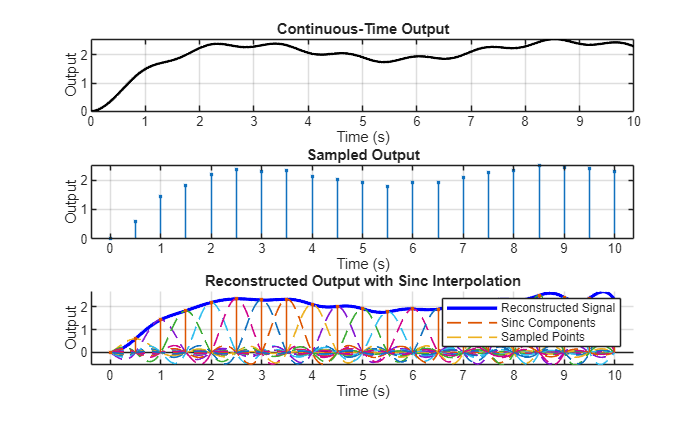

clc; clear; close all;

% Given continuous-time system (Linearized and reduced model of the Fan and
% Plate System)
Gs = tf([5.378e-08 - 0.0004139 1.065], [1 5.333 4.942]);

% Sampling parameters
Ts = 0.5;   % Sampling period
Fs = 1/Ts;  % Sampling frequency
t_max = 10;  % Duration of simulation
t_cont = linspace(0, t_max, 1000); % Fine grid for continuous-time response

% Define input function u(t) = 10 + 2sin(t) + 3sin(5t - pi/3)
u_cont = 10 + 2*sin(t_cont)+3*sin(5*t_cont - pi/3);

% Compute continuous-time output using lsim
y_cont = lsim(Gs, u_cont, t_cont);

% Discrete-time sampling
t_samp = 0:Ts:t_max; % Sample times
u_samp = 10 + 2*sin(t_samp) + 3*sin(5*t_samp - pi/3); % Sampled input
y_samp = lsim(Gs, u_samp, t_samp); % Sampled output

% Reconstruction using sinc interpolation
t_recon = linspace(0, t_max, 1000); % Fine time grid for reconstruction
y_recon = zeros(size(t_recon));

% Compute sinc components
sinc_components = zeros(length(t_samp), length(t_recon));

for k = 1:length(t_samp)
    sinc_func = sinc(Fs * (t_recon - t_samp(k))); % Ideal sinc function
    sinc_components(k, :) = y_samp(k) * sinc_func;
    y_recon = y_recon + sinc_components(k, :);
end

% Plot results in subplots
figure;

% Subplot 1: Continuous output
subplot(3,1,1);
plot(t_cont, y_cont, 'k', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Output');
title('Continuous-Time Output'); grid on;

% Subplot 2: Sampled output
subplot(3,1,2);
stem(t_samp, y_samp, '.', 'MarkerFaceColor', 'b');
% stem(t_samp, y_samp, 'b');
xlabel('Time (s)'); ylabel('Output');
title('Sampled Output'); grid on;

subplot(3,1,3);
hold on;
plot(t_recon, y_recon, 'b', 'LineWidth', 2); % Reconstructed signal
for k = 1:length(t_samp)
    plot(t_recon, sinc_components(k, :), '--', 'LineWidth', 1); % Individual sinc components
end
stem(t_samp, y_samp, '.', 'MarkerFaceColor', 'b'); % Sampled points
xlabel('Time (s)'); ylabel('Output');
title('Reconstructed Output with Sinc Interpolation');
legend('Reconstructed Signal', 'Sinc Components', 'Sampled Points');
grid on;
hold off;

**Exercise for the reader**: Consider the VTOL system. Plot the continous output, the sampled output for T=0.1 and T=1 and the reconstructed outputs for inputs u=5 and y=2sin(3t).  You can use the code above as a template and simply change the lines defining the input and output.

% System definition with a given initial condition
speed= 2*pi*500/60;

Section 2.1.1 below


x0 = [ 0; speed; 0; 0];
sys = OneDofAeroVTOL_model_control101(x0); 

## 2 Alternatives to an ideal filter

Common alternatives to an ideal filter and the first-order and zero-order hold. Zero-order hold and first-order hold approximations are based on Taylor expansion of a continuous signal at time $\textrm{kT}$ which is given below. 

### 
$$f_k \left(t\right)=f\left(\textrm{kT}\right)+f^{\left(1\right)\;} \left(\textrm{kT}\right)\left(t-\textrm{kT}\right)+\frac{1}{2!}f^{\left(2\right)\;} \left(\textrm{kT}\right){\left(t-\textrm{kT}\right)}^{2\;} +\;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp$$


### **2.1 Zero-order Hold (z.o.h)**

When only the first term of the Taylor expansion is considered for reconstruction, namely when the following approximation is used, the zero-order hold is obtained.

### $f_k \left(t\right)=f\left(\textrm{kT}\right)$ ,  $\textrm{kT}\le t<\left(k+1\right)T$

The impulse response of zero-order hold is given in Figure 5, which is:

### 
$$g_{{\textrm{zoh}}_{\textrm{imp}} } \left(t\right)=u\left(t\right)-u\left(t-T\right)$$


where $u\left(t\right)$ is unit step function and its Laplace Transform. Namely the transfer function of zero-order hold is as given below.  Figure 5 illustrates the operation.

### 
$$G_{\textrm{zoh}} \left(s\right)=\frac{1}{s}-\frac{e^{-\textrm{sT}} }{s}=\frac{1-e^{-\textrm{sT}} }{s}$$


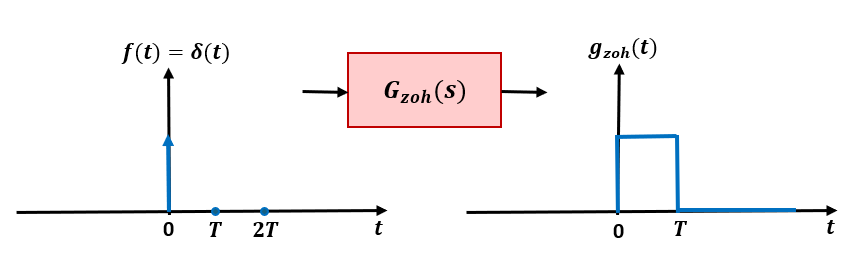

Figure 5. Impulse response of zero-order hold

In Figure 6, the reconstruction of a continous signal with a zero-order hold is shown.

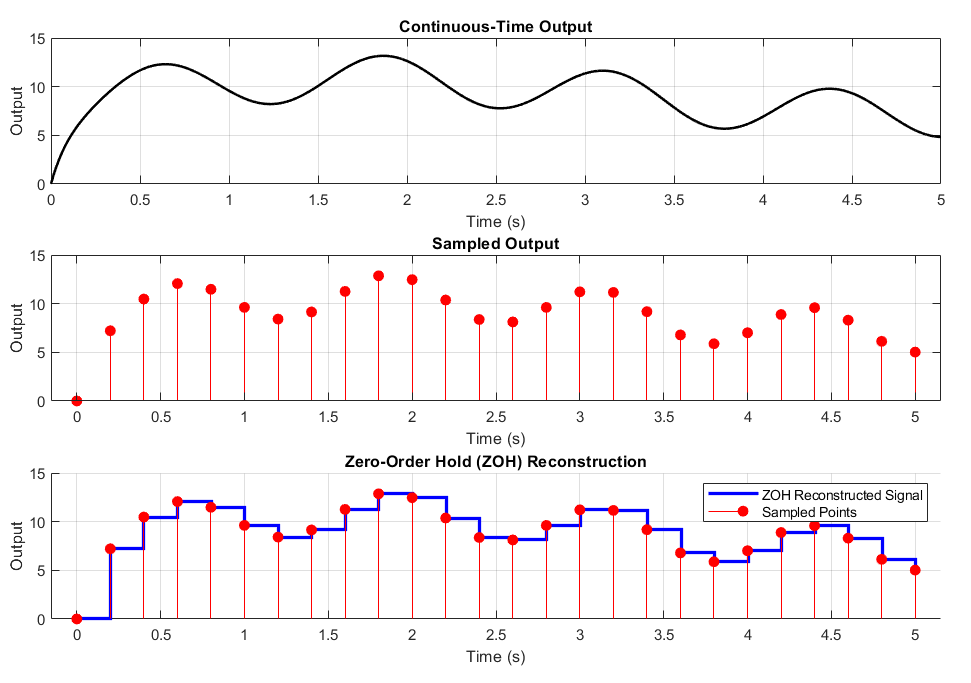

Figure 6.  Reconstruction of continous time signal with zero-order hold

#### 2.1.1 Illustration of a zero hold with MATLAB code

Consider linearized and reduced model of the Fan and Plate system. Following example plots the continous-time output, sampled output with T=0.5 and reconstructed-continous output with zero-order hold for the input u = 10 + 2sin(t) + 3sin(5t - pi/3).

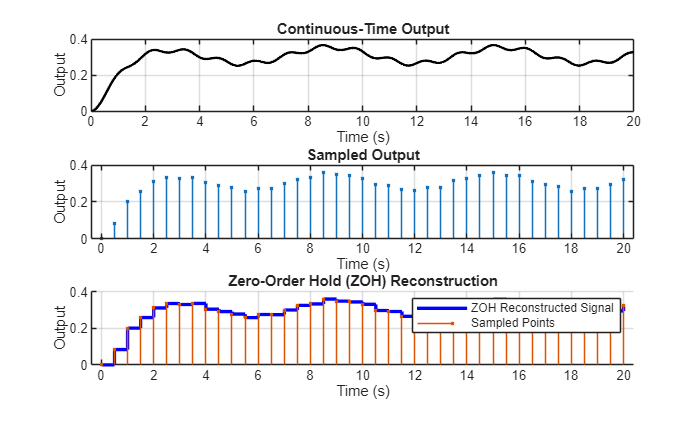

disp('Section 2.1.1 below')
clc; clear; close all;

Gs=FanAndPlate_model_control101;

% Given continuous-time system
%Gs = tf([5.378e-08 - 0.0004139 1.065], [1 5.333 4.942]);

% Sampling parameters
Ts = 0.5;   % Sampling period
t_max = 20;  % Duration of simulation
t_cont = linspace(0, t_max, 1000); % Fine grid for continuous-time response

% Define input function u(t) = 10 + 2sin(t) + 3sin(5t - pi/3)
u_cont = 10 + 2*sin(t_cont) + 3*sin(5*t_cont - pi/3);

% Compute continuous-time output using lsim
y_cont = lsim(Gs, u_cont, t_cont);

% Discrete-time sampling
t_samp = 0:Ts:t_max; % Sample times
u_samp = 10 + 2*sin(t_samp) + 3*sin(5*t_samp - pi/3); % Sampled input
y_samp = lsim(Gs, u_samp, t_samp); % Sampled output

% Zero-Order Hold (ZOH) Reconstruction
t_recon = linspace(0, t_max, 1000); % Fine time grid for reconstruction
y_recon = interp1(t_samp, y_samp, t_recon, 'previous'); % ZOH interpolation

% Plot results in subplots
figure;

% Subplot 1: Continuous output
subplot(3,1,1);
plot(t_cont, y_cont, 'k', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Output');
title('Continuous-Time Output'); grid on;

% Subplot 2: Sampled output
subplot(3,1,2);
stem(t_samp, y_samp, '.', 'MarkerFaceColor', 'b');
xlabel('Time (s)'); ylabel('Output');
title('Sampled Output'); grid on;

% Subplot 3: Zero-Order Hold (ZOH) Reconstruction
subplot(3,1,3);
hold on;
stairs(t_recon, y_recon, 'b', 'LineWidth', 2); % ZOH reconstructed signal
stem(t_samp, y_samp, '.', 'MarkerFaceColor', 'b'); % Sampled points
xlabel('Time (s)'); ylabel('Output');
title('Zero-Order Hold (ZOH) Reconstruction');

legend('ZOH Reconstructed Signal', 'Sampled Points');
grid on;
hold off;


#### **2.1.2 Exercise for the reader**

Consider the VTOL system. Plot the continuous output, sampled output for T=0.2 , T=1  and T=2, and reconstructed outputs with a zero-order hold for inputs u=5 and y=2sin(3t).  The code in section 2.1.1. can be used as a template and needs only minor changes.

% System definition with a given initial condition
speed= 2*pi*500/60;
x0 = [ 0; speed; 0; 0];
sys = OneDofAeroVTOL_model_control101(x0); 

### **2.2 First Order Hold (f.o.h)**

When the first two term of the Taylor expansion is considered for reconstruction, namely when the following approximation is used, the first-order hold is obtained.

### $f_k \left(t\right)=f\left(\textrm{kT}\right)+f^{\left(1\right)\;} \left(\textrm{kT}\right)\left(t-\textrm{kT}\right)$, $\textrm{kT}\le t<\left(k+1\right)T$

The impulse response of zero-order hold is given in Figure 7, which is:

### 
$$g_{{\textrm{foh}}_{\textrm{imp}} } \left(t\right)=u\left(t\right)+\frac{1}{T}t\;u\left(t\right)-2u\left(t-T\right)-\frac{2}{T}\left(t-T\right)\;u\left(t-T\right)+u\left(t-2T\right)+\frac{1}{T}\left(t-2T\right)\;u\left(t-2T\right)$$


where $u\left(t\right)$ is unit step function and its Laplace Transform, namely transfer function of first-order hold is as given below.

### 
$$G_{\textrm{foh}} \left(s\right)=\frac{{\left(1-e^{-\textrm{Ts}} \right)}^2 }{{\textrm{Ts}}^{2\;} }\left(\textrm{Ts}+1\right)$$


This can be rewritten in terms of transfer function of zero-order hold as follows (and illustrated in Figure 7).

### 
$$G_{\textrm{foh}} \left(s\right)$$

$$=\left(\frac{1+T\;s\;}{T}\right){G^{2\;} }_{\textrm{zoh}} \left(s\right)$$


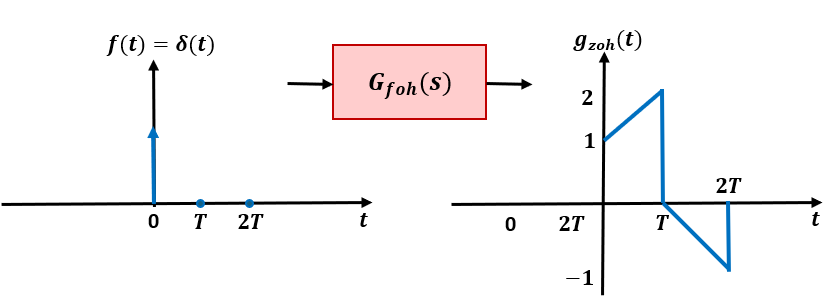

Figure 7. Impulse response of first-order hold

In Figure 8, the reconstruction of a continous signal with first-order hold is shown.

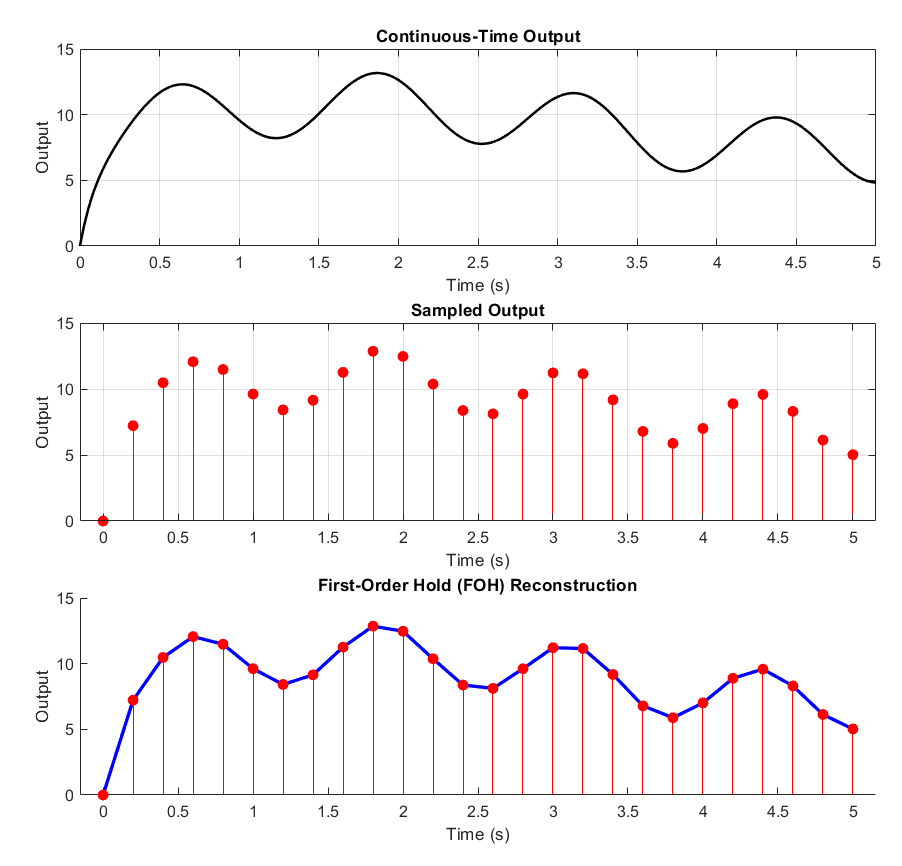

Figure 8.  Reconstruction of continous time signal with first-order hold

#### 2.1.1 Illustration of a zero hold with MATLAB code

Consider linearized and reduced model of the Fan and Plate system. Following example plots the continous-time output, sampled output with T=0.5 and reconstructed-continous output with first-order hold for the input u = 10 + 2sin(t) + 3sin(5t - pi/3).

disp('Section 2.2.1 below')

Section 2.2.1 below


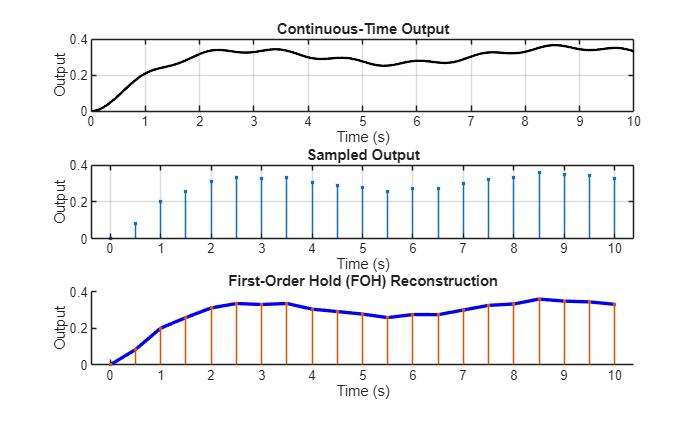

clc; clear; close all;

% Given continuous-time system
%Gs = tf([5.378e-08 - 0.0004139 1.065], [1 5.333 4.942]);
Gs=FanAndPlate_model_control101;

% Sampling parameters
Ts = 0.5;   % Sampling period
t_max = 10;  % Duration of simulation
t_cont = linspace(0, t_max, 1000); % Fine grid for continuous-time response

% Define input function u(t) = 10 + 2sin(t) + 3sin(5t - pi/3)
u_cont = 10 + 2*sin(t_cont) + 3*sin(5*t_cont - pi/3);

% Compute continuous-time output using lsim
y_cont = lsim(Gs, u_cont, t_cont);

% Discrete-time sampling
t_samp = 0:Ts:t_max; % Sample times
u_samp = 10 + 2*sin(t_samp) + 3*sin(5*t_samp - pi/3); % Sampled input
y_samp = lsim(Gs, u_samp, t_samp); % Sampled output

% First-Order Hold (FOH) Reconstruction (Linear Interpolation)
t_recon = linspace(0, t_max, 10/Ts+1); % Fine time grid for reconstruction
y_recon = interp1(t_samp, y_samp, t_recon, 'linear'); % FOH interpolation

% Plot results in subplots
figure
% Subplot 1: Continuous output
subplot(3,1,1);
plot(t_cont, y_cont, 'k', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Output');
title('Continuous-Time Output'); grid on;

% Subplot 2: Sampled output
subplot(3,1,2);
stem(t_samp, y_samp, '.', 'MarkerFaceColor', 'b');
xlabel('Time (s)'); ylabel('Output');
title('Sampled Output'); grid on;

% Subplot 3: First-Order Hold (FOH) Reconstruction
subplot(3,1,3);
hold on;
plot(t_recon, y_recon, 'b', 'LineWidth', 2); % FOH reconstructed signal
stem(t_samp, y_samp, '.', 'MarkerFaceColor', 'b'); % Sampled points
xlabel('Time (s)'); ylabel('Output');
title('First-Order Hold (FOH) Reconstruction')

### **2.2.2 Exercises for the reader**

- Consider the VTOL system. Plot continous output, sampled output for T=0.2 and T=1 and reconstructed outputs with first-order hold for inputs u=5 and y=2sin(3t)

- Investigate the effect of reconstruction and signal holders in virtual laboratory named ***Digital_to_Analog_Converter_Application.mlapp***

% System definition with a given initial condition
speed= 2*pi*500/60;
x0 = [ 0; speed; 0; 0];
sys = OneDofAeroVTOL_model_control101(x0); 

## ***3 Virtual laboratories***

The file*** Digital_to_Analog_Converter_Application_control101.mlapp ***allows users to explore the DAC for a range of settings set by sliders.  The operation of this app is rather self-explanatory.

It utlises a simulink file ***DACmodel_control101.slx***.

- Understand the technical principles of the digital-to-analog (D/A) conversion process, including signal reconstruction from discrete-time samples.

-  Analyze how discrete-time signals are transformed into continuous-time outputs by studying the effects of reconstruction methods such as zero-order hold, first-order hold on the resulting time-domain data.

- Perform numerical experiments to observe and investigate how sampling period, update rate, and reconstruction methodology or approximation affect DAC and signal behaviour within simulation app.

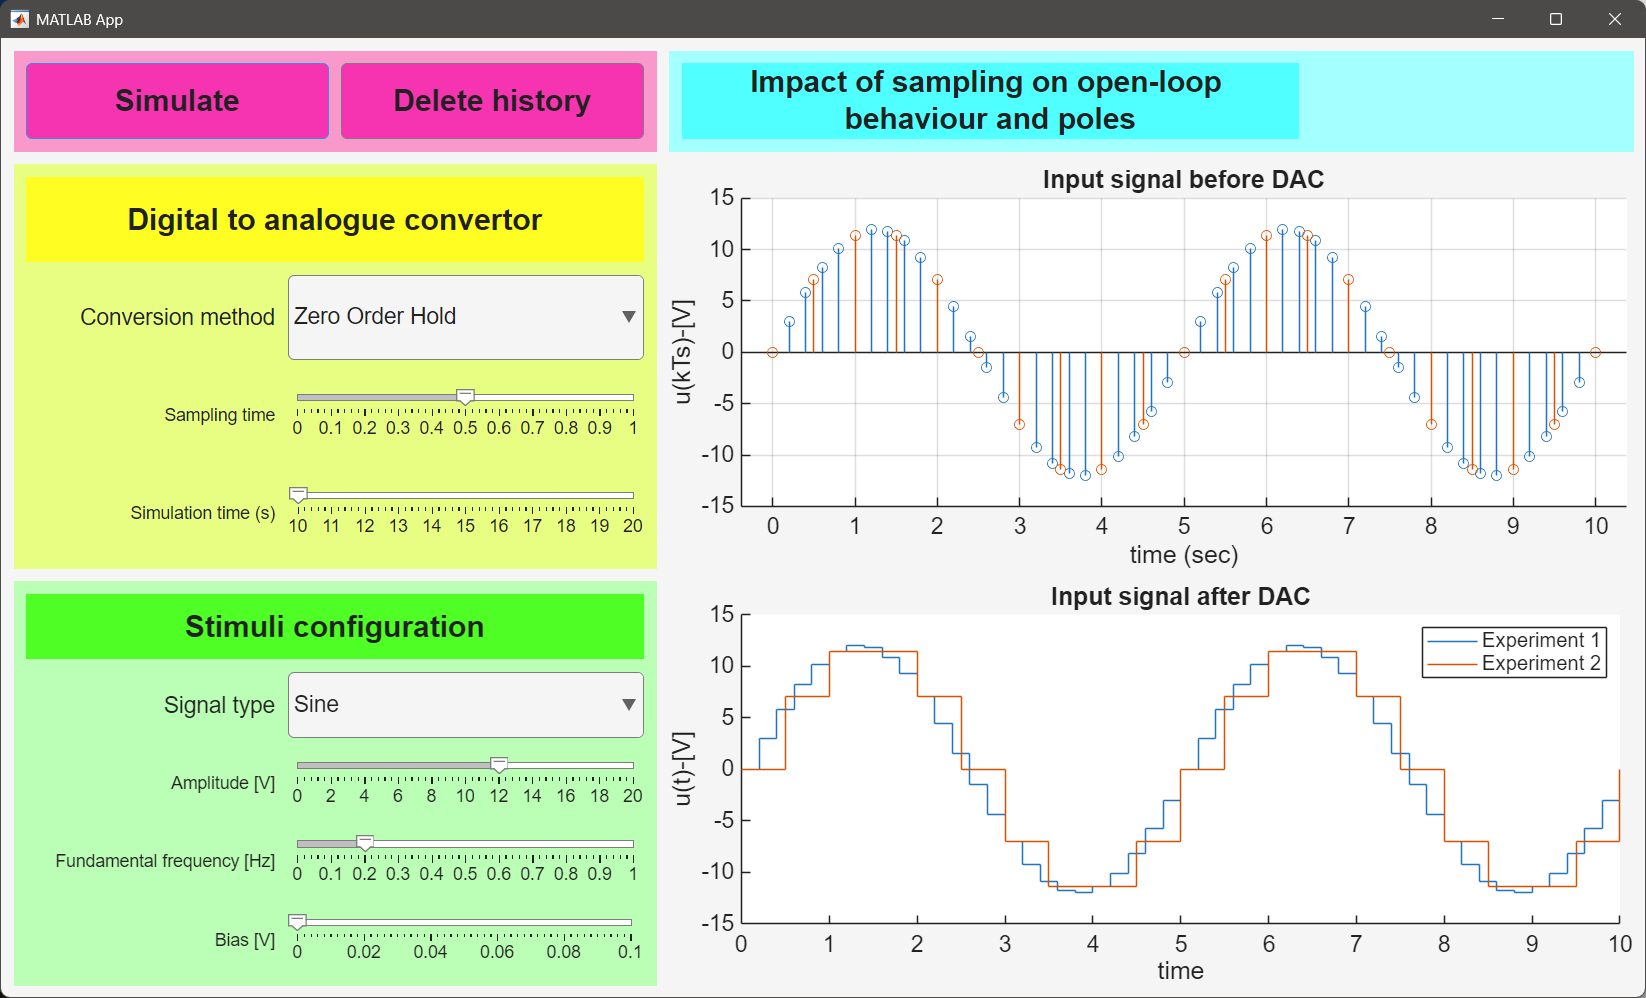

## References

[1] Wittenmark, Björn, Karl-Erik Årzén, and Karl Johan Åström. "Computer control: An overview." *IFAC Professional Brief* , 2002.

[2] Goren-Sumer, Leyla, Bilgisayar Kontrollü Sistemler ders slaytları (Lecture slides of Computer-Controlled Systems), 2021.

[3] Ogata, Katsuhiko. *Discrete-time control systems*. Prentice-Hall, Inc., 1995.

Note: Some assistance from ChatGPT was used in developing the MATLAB codes of examples.